clc; clear; close all
rng("default")

% 2D
C = 27;
d = 4;

load(['FC_data/A_d',num2str(d),'_C', num2str(27), '.mat']);
load(['FC_data/Q_d',num2str(d),'_C', num2str(27), '.mat']);
A = double(A);
Q = double(Q);

l_theta = @(theta) [2*sin(theta/2), -sin(theta)];

n_lst = 20 * 2.^(0:4)

n_lst =     20    40    80   160   320


h_lst = 0.029 * (1/2).^(0:4);

C2_patches = cell(length(n_lst), 1);
C2_norms = cell(length(h_lst), 1);

% Construct FC Patches
for i=3%1:length(n_lst)
    n_C2 = n_lst(i);
    h_S = h_lst(i);
    n_S = n_C2; % 10;%ceil(21/20*n_C2);
    
    C2_patch = construct_C2_patch(@(x, y) f(x, y), 0.4, 2*pi-0.4, 0, n_C2, n_C2);
    C2_fcont_patch = C2_patch.FC(C, d, A, Q, nan);
    
    C2_fcont_patch.compute_xi_eta_fc_coeffs();
    
    [C2_bound_X, C2_bound_Y] = C2_patch.boundary_mesh_xy();
    R_FFT = R_cartesian_mesh_obj(C2_fcont_patch.x_min, C2_fcont_patch.x_max, C2_fcont_patch.y_min, C2_fcont_patch.y_max, h_S, C2_bound_X, C2_bound_Y);

    R_FFT.interpolate_patch(C2_fcont_patch, 5, true);
    max(abs(R_FFT.f_R(R_FFT.interior_idxs) - f(R_FFT.R_X(R_FFT.interior_idxs), R_FFT.R_Y(R_FFT.interior_idxs))))
    
    R_FFT.compute_fc_coeffs();
    [R_X_err, R_Y_err, f_interpolation, interior_idx] = R_FFT.ifft_interpolation(R_FFT.h./2);

    max(abs(f(R_X_err(interior_idx), R_Y_err(interior_idx))-f_interpolation(interior_idx)))
    
    save("R_FFT", "R_FFT")
%     
%     save("C2_fcont_patch_test", "C2_fcont_patch")
%     save("C2_patch_test", "C2_patch")
end

start first pass
construct nan map


ans = 8.9015e-09

ans = 8.9617e-09

% [xi, eta] = C2_fcont_patch.inverse_M_p(-0.132045, -0.132509, nan)
[xi, eta] = C2_fcont_patch.inverse_M_p(-0.197295, 0.0704913, nan)

xi = -0.3353

eta = -0.1582

C2_fcont_patch.locally_compute(xi, eta, 5, true)

ans = 9.5524e-16

C2_fcont_patch.locally_compute_FFT(xi, eta)

ans = 9.0886e-11

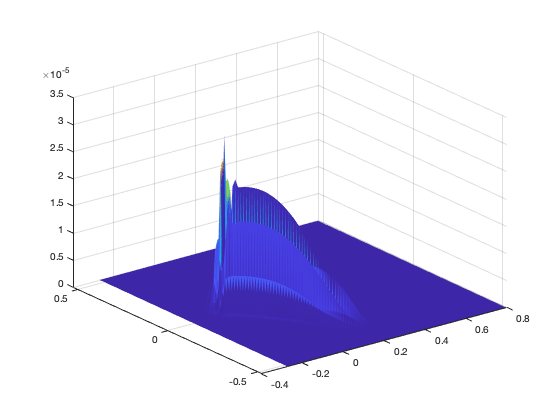

s =   Surface with properties:

       EdgeColor: 'none'
       LineStyle: '-'
       FaceColor: 'flat'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [146×148 double]
           YData: [146×148 double]
           ZData: [146×148 double]
           CData: [146×148 double]

  Show all properties


clc; clear; close all;

load("R_FFT.mat")
load("R_poly.mat")
load("C2_fcont_patch_test.mat")
load("C2_patch_test.mat")

figure;
s = surf(R_FFT.R_X, R_FFT.R_Y, abs(R_poly.f_R-R_FFT.f_R));
s.EdgeColor = 'none'

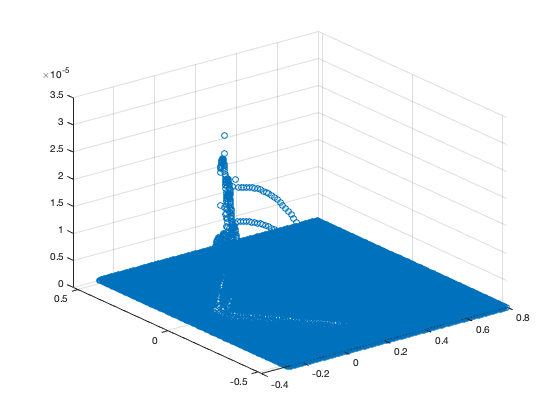


figure;
scatter3(R_FFT.R_X(:), R_FFT.R_Y(:), abs(R_poly.f_R(:)-R_FFT.f_R(:)));


err = abs(R_poly.f_R-R_FFT.f_R);
figure;
scatter(R_FFT.R_X(:), R_FFT.R_Y(:), 100, err(:), 'filled');

% Add a color bar
colorbar;

% Set colormap
colormap(jet);

hold on;

test_point = [-0.124795; 0.0197413]

test_point =    -0.1248
    0.0197


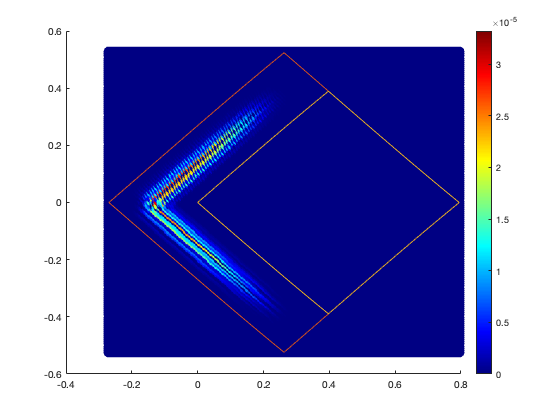


[bound_X, bound_Y] = C2_fcont_patch.boundary_mesh_xy();
plot(bound_X, bound_Y)

[bound_X, bound_Y] = C2_patch.boundary_mesh_xy();
plot(bound_X, bound_Y);

[test_point_xi, test_point_eta] = C2_fcont_patch.inverse_M_p(test_point(1), test_point(2), nan)

test_point_xi =     -1.807461372529699e-01


test_point_eta =     -1.312958141908376e-01



C2_fcont_patch.locally_compute(test_point_xi, test_point_eta, 7, true)

xi_j =     12


eta_j =     16


interpol_xi_mesh =     -2.250000000000000e-01
    -2.125000000000000e-01
    -2.000000000000000e-01
    -1.875000000000000e-01
    -1.750000000000000e-01
    -1.625000000000000e-01
    -1.500000000000000e-01
    -1.375000000000000e-01


interpol_eta_mesh =     -3.250000000000000e-01
    -3.125000000000000e-01
    -3.000000000000000e-01
    -2.875000000000000e-01
    -2.750000000000000e-01
    -2.625000000000000e-01
    -2.500000000000000e-01
    -2.375000000000000e-01
    -2.250000000000000e-01
    -2.125000000000000e-01


interpol_eta_exact =      1.540709959149176e-03
     5.604018045801219e-03
     1.577121023081722e-02
     3.514831062725132e-02
     6.346467309278973e-02
     9.521461775300344e-02
     1.224116072686294e-01
     1.400398446461272e-01


ans =      4.958189557631332e-02


C2_fcont_patch.locally_compute_FFT(test_point_xi, test_point_eta)

ans =      4.965331468102305e-02


%C2_fcont_patch.locally_compute(-0.225, -0.175, 7, true)

function C2_patch = construct_C2_patch(f, theta_A, theta_B, theta_C, n_xi, n_eta)
    l_theta = @(theta) [2*sin(theta/2), -sin(theta)];
    
    l_A = @(xi) xi*(theta_A - theta_C) + theta_C;
    l_B = @(eta) eta*(theta_B - theta_C - 2*pi) + theta_C + 2*pi; % account for wrap around
    
    M_p = @(xi, eta) l_theta(l_A(xi)) + l_theta(l_B(eta)) - l_theta(theta_C);
    J = @(v) [theta_A*cos(v(1)*theta_A/2) (theta_B-2*pi)*cos((v(2)*(theta_B-2*pi)+2*pi)/2); -theta_A*cos(v(1)*theta_A) -(theta_B-2*pi)*cos(v(2)*(theta_B-2*pi)+2*pi)];
    
    xi_mesh = linspace(0, 1, n_xi+1);
    eta_mesh = linspace(0, 1, n_eta+1);
    
    [XI, ETA] = meshgrid(xi_mesh, eta_mesh);
    XY = M_p(XI(:), ETA(:));
    
    f_XY = reshape(f(XY(:, 1), XY(:, 2)), [n_eta+1, n_xi+1]);
    
    C2_patch = C2_patch_old_obj(M_p, J, n_xi, n_eta, 0, 1, 0, 1, f_XY, nan); % data associated with patch
end

function S_patch = construct_S_patch(f, theta_A, theta_B, h, n_xi, n_eta)
    l_theta = @(theta) [2*sin(theta/2), -sin(theta)];
    
    l_A = @(xi) (theta_B - theta_A)*xi + theta_A;
    nu = @(xi) [cos(l_A(xi)), cos(l_A(xi)/2)] ./ sqrt(cos(l_A(xi)).^2 + cos(l_A(xi)/2).^2);
    
    M_p_general = @(xi, eta, H) l_theta(l_A(xi)) + eta.*H.*nu(xi);
    % H is a function of h and n_eta
    
    theta_diff = theta_B - theta_A;
    J = @(v, H) [theta_diff*cos(l_A(v(1))/2)-v(2)*H*theta_diff*sin(l_A(v(1))), H*cos(l_A(v(1))); -1*theta_diff*cos(l_A(v(1)))-v(2)*H*theta_diff/2*sin(l_A(v(1))/2), H*cos(l_A(v(1))/2)];
    
    xi_mesh = linspace(0, 1, n_xi+1);
    eta_mesh = linspace(0, 1, n_eta+1);
    
    [XI, ETA] = meshgrid(xi_mesh, eta_mesh);
    XY = M_p_general(XI(:), ETA(:), h*n_eta);
    
    f_XY = reshape(f(XY(:, 1), XY(:, 2)), [n_eta+1, n_xi+1]);
    
    S_patch = S_patch_obj(M_p_general, J, n_xi, n_eta, 0, 1, 0, 1, f_XY, h, nan);
end

function f_y = f(x, y)
    r = sqrt(x.^2 + y.^2);
    f_y = zeros(size(x));
    f_y(r < 0.56) = exp(1./(1/0.56*r(r < 0.56).^2-0.56));
    f_y(r >= 0.56) = 0;
end

function f_y = f_smooth(x, y)
    f_y = zeros(size(x));
    interior_msk = x < 1 & x > 0 & y < 1 & y > 0;
    f_y(interior_msk) = exp(-1./(1-(2*x(interior_msk)-1).^2)).*exp(-1./(1-(2*y(interior_msk)-1).^2));
end